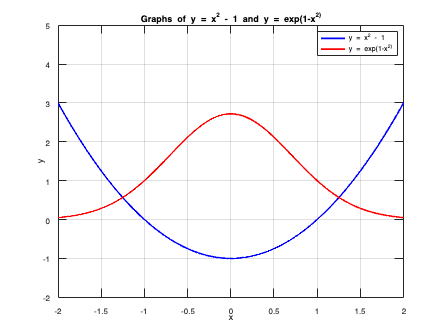

% Noah Semashkewich
% 53882783

clear;clc;

% Define the range of x values
x = linspace(-2, 2, 1000);

% Calculate the corresponding y values for each function
y1 = x.^2 - 1;
y2 = exp(1 - x.^2);

% Plot the graphs
figure;
plot(x, y1, 'b', 'LineWidth', 2); % Plot y = x^2 - 1 in blue
hold on;
plot(x, y2, 'r', 'LineWidth', 2); % Plot y = exp(1-x^2) in red

% labels and legend
xlabel('x');
ylabel('y');
title('Graphs of y = x^2 - 1 and y = exp(1-x^2)');
legend('y = x^2 - 1', 'y = exp(1-x^2)');
grid on;

% Axis bounds
xlim([-2, 2]);
ylim([-2, 5]);

% Show the plot
hold off;


% Function f(x) and interval
f = @(x) x^2 - 1 - exp(1 - x^2);
a = -2;
b = 0;

% Call the bisection method
root = bisection(f, a, b);

% Display the root
disp(['Approximation to the root: ', num2str(root)]);

Approximation to the root: -1.251


function root = bisection(f, a, b) % Bisection function used from team challenges topic 2. Edited to fit question.
    % Check for different signs
    if f(a)*f(b) >= 0
        disp("No root found.");
        root = NaN;
        return;
    end

    while (b - a) / 2 > 10^-3
        c = (a + b) / 2;
        if f(c) == 0 % If f(c) == 0, then the root has been found
            root = c;
            disp('Root found.');
            return;
        elseif f(c) * f(a) < 0 % If f(c)*f(a) < 0, interval moves towards a
            b = c;
        else % Else, interval moves towards c
            a = c;
        end
    end

    root = (a + b) / 2;
end